# German Stocks - Exploring I

## 1.

Load the table stored in the file `daxReturns.mat`.

load daxReturns

## 2.

Extract the data for the financial stocks named `Allianz`, `DeutscheBank`, and `Commerzbank` into a separate variable.

finLabels = {'Allianz','DeutscheBank','Commerzbank'};
finance = daxReturns{:,finLabels}

finance =    -0.0209   -0.0106    0.0207
    0.0206    0.0177    0.0143
    0.0046    0.0138    0.0114
    0.0030    0.0054   -0.0007
   -0.0066   -0.0066   -0.0053
   -0.0097   -0.0047   -0.0034
   -0.0195    0.0007    0.0037
    0.0044    0.0127    0.0436
   -0.0146   -0.0063   -0.0165
   -0.0028    0.0069    0.0107


## 3.

Extract the data for the energy stocks named `RWE` and `EON` into a separate variable.

enLabels = {'RWE','EON'};
energy = daxReturns{:,enLabels}

energy =     0.0087   -0.0022
    0.0179    0.0321
    0.0033    0.0093
   -0.0007   -0.0025
   -0.0050   -0.0013
   -0.0162   -0.0132
   -0.0060   -0.0034
    0.0030    0.0090
   -0.0033   -0.0039
   -0.0075   -0.0117


## 4.

Visually compare the two new data sets using the function `plotmatrix`.

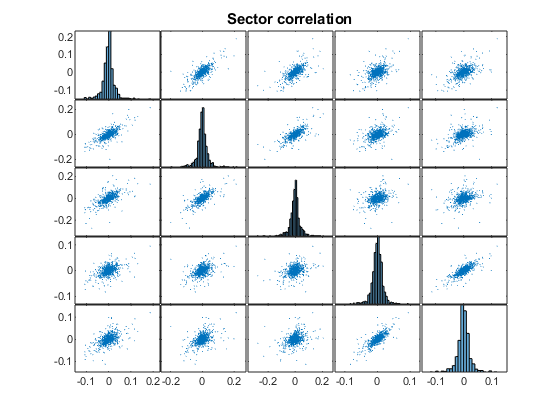

plotmatrix([finance, energy]);
title('Sector correlation')

## BONUS

Calculate the matrix of correlation coefficients and display it using the function `imagesc`.

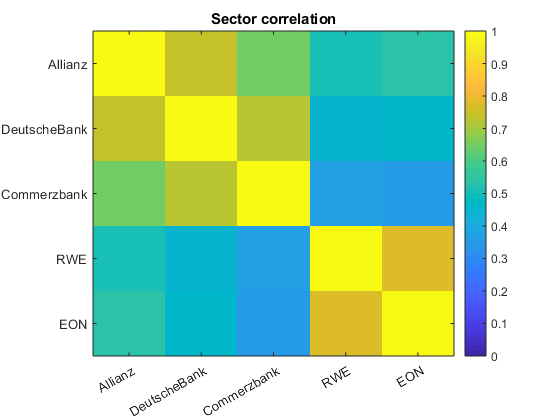

c = corrcoef([finance, energy]);
imagesc(c,[0,1])
title('Sector correlation')
colorbar

yticks(1:5);
yticklabels([finLabels,enLabels]);
xticks(1:5);
xticklabels([finLabels,enLabels]);
xtickangle(30);